# Linear Quarter Car Model

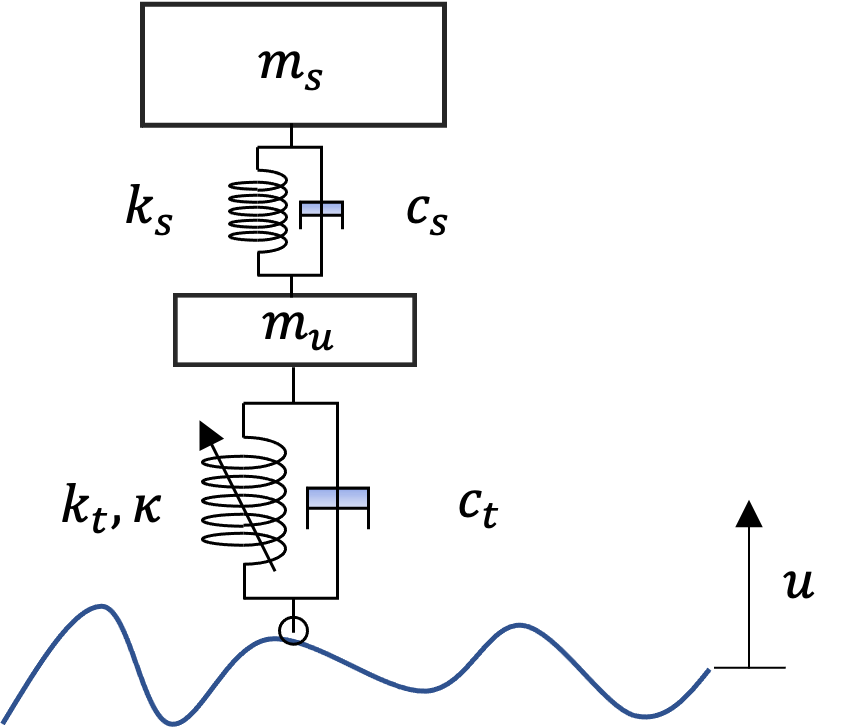

## Generate model

n=2; kappa=2e3;
[M,C,K,fnl,f_0] = build_model(kappa,n);

## Dynamical system setup 

We consider the stochastic forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}_{nl}(\mathbf{x},\dot{\mathbf{x}})=\mathbf{f}_{stochastic}(\mathbf{x},t)$$


nRealization = 96;
T0 = 50; %% PSD frequency domain resolution is ~ 1/T0
nPoints = 2^15; %% control the accuracy of numerical differential equation
epsilon = 1; %% forcing magnitude
[samplePSD,forcingdof,stochastic_f] = build_stochasticF(n,nPoints,epsilon,kt,ct);
SS = StochasticSystem();
set(SS,'samplePSD',samplePSD,'linear',false)
set(SS,'M',M,'C',C,'K',K,'fnl',fnl);
set(SS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
set(SS.SSOptions,'ssMethod','direct','tol',1e-12)
SS.add_random_forcing(nRealization, T0, nPoints,forcingdof);

We assume stochastic forcing of the form that has a specific PSD. We identify the stochastic forcing by input a white noise to a second order system:

                                            
$$\mathbf{M_i}\ddot{\mathbf{x}}+\mathbf{C_i}\dot{\mathbf{x}}+\mathbf{K_i}\mathbf{x}=\mathbf{W}_{white noise}$$


We take the PSD of the response $<\mathbf x_1,\mathbf x_1>$ over the time domain as the input to the Quarter Car system

setting for the SDE solver and allocate desired output PSD pairs

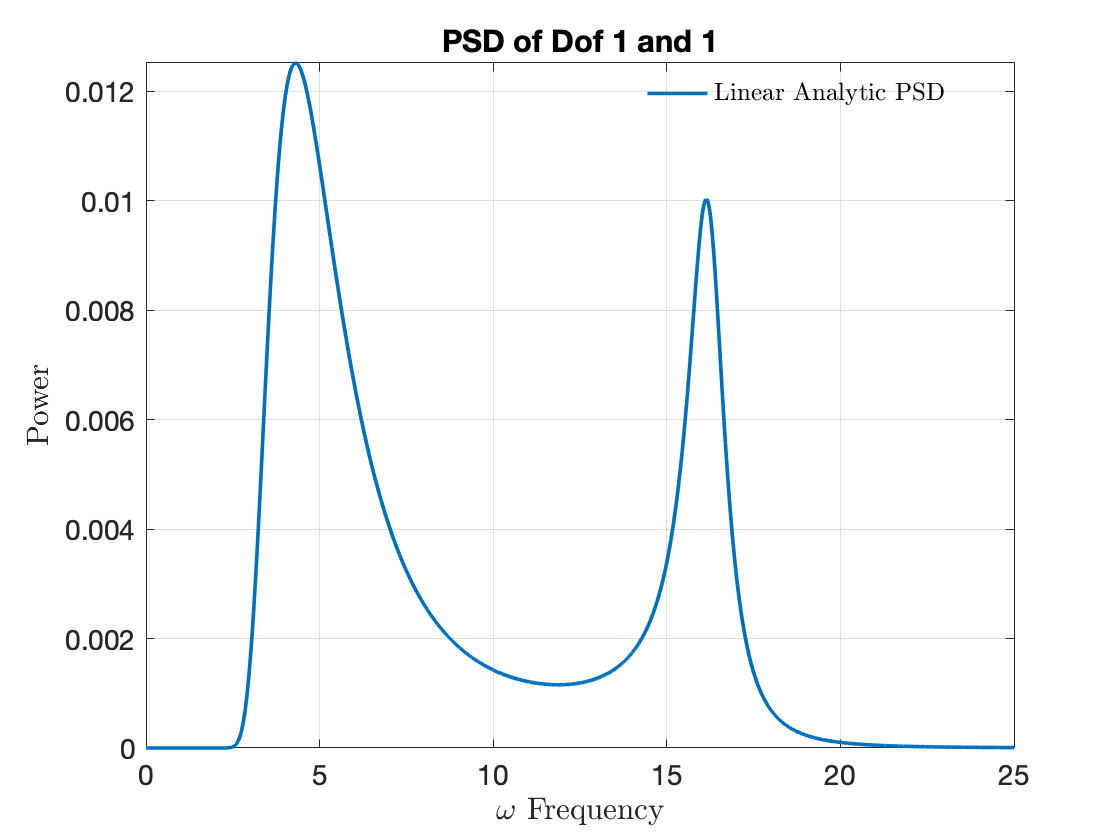

method="Newmark";

PSDpair=[1,1];
[V,D,~] = SS.linear_spectral_analysis();
first_res = abs(imag(D(1)));

## Solve full system

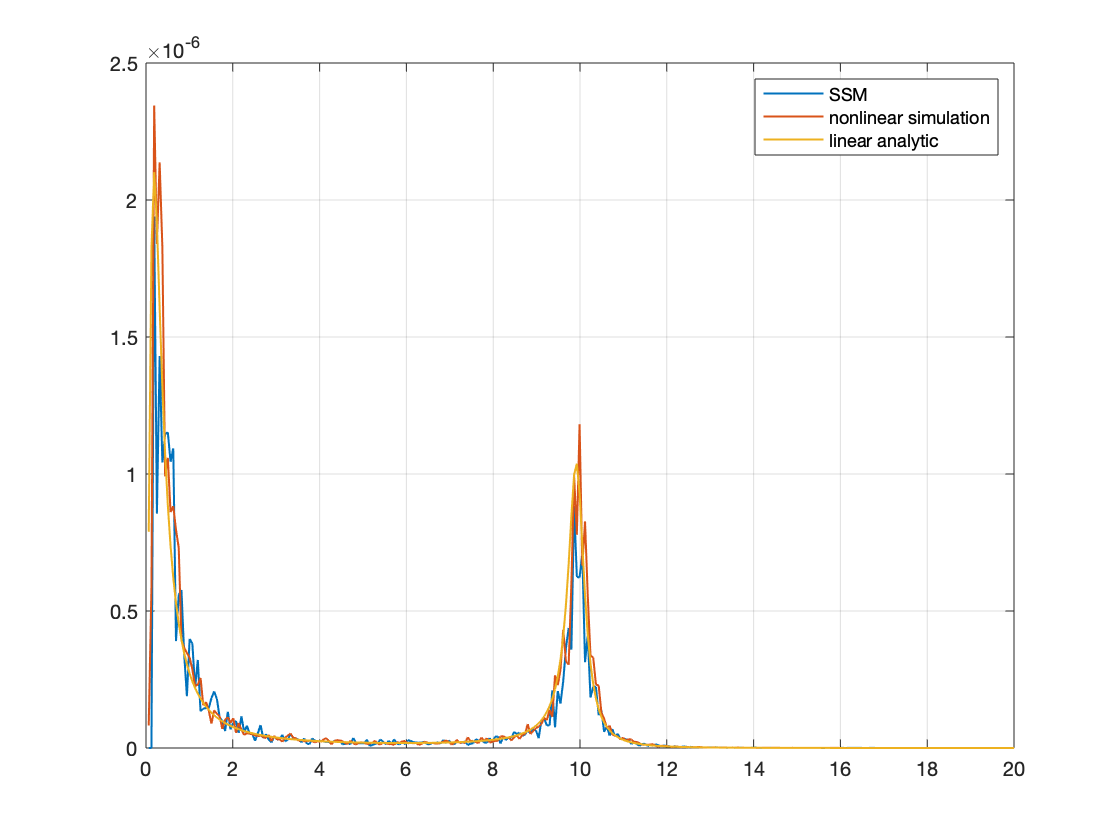

tic

[w,outputPSD] = SS.monte_carlo_average(method,PSDpair,nRealization);
time_sde = toc;
disp(['Total number of ',num2str(nRealization),'# realization takes ',...
    num2str(time_sde),' amount of time'])

## Calculation of linear response

[w_linear,linear_analytic]=SS.compute_linear_PSD(PSDpair,[0,25]);

## SSM setting and compute PSD from SSM

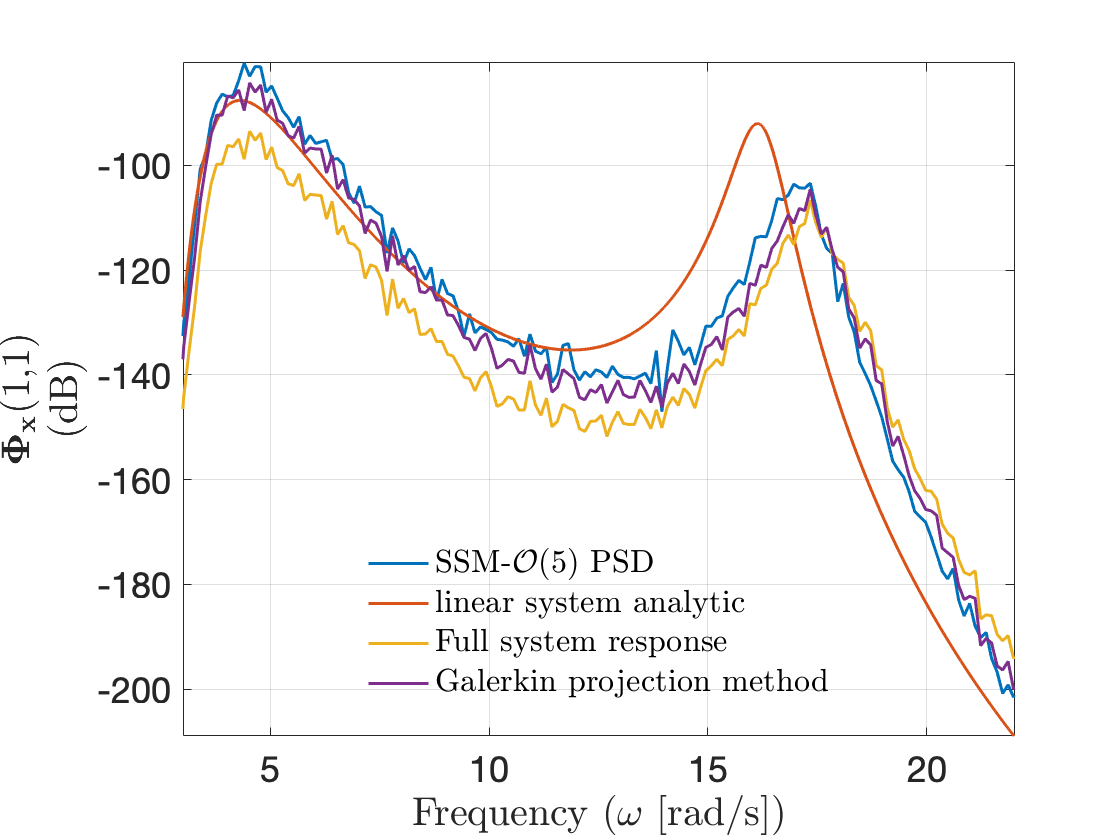

S = SSM(SS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
masterModes = [1,2];
S.choose_E(masterModes);
order = 5; % Approximation order

S.ssmSEulerTimeDisp = false; S.tol= 1e-12;
tic
[wss,ssmPSD]=S.extract_PSD(PSDpair, order,'direct heun',[0 25]);
time_ssm=toc;
disp([num2str(time_ssm),' amount of time in SSM computation'])

## Compute PSD from Galerkin

SS.nRealization = 1;
tic
[w_galerkin, PSD_galerkin] =  SS.monte_carlo_galerkin(method, PSDpair);
time_galerkin = toc;
disp(['Total number of ',num2str(nRealization),'# realization in Galerkin projection takes ',...
    num2str(time_galerkin),' amount of time'])

## Compare the results of SSM, Galerkin Projection, full system response and linear response

clear omega
clear Gxx
omega.w = w; Gxx.Gfull = outputPSD;%outputPSD;
omega.linear = w_linear; Gxx.linear_analytic = linear_analytic;
omega.wss = wss; Gxx.Gss = ssmPSD;
omega.w_galerkin = w_galerkin; Gxx.galerkin = PSD_galerkin;

plot_log_PSD(omega,Gxx,order,PSDpair,[3 22],true)